Set some parameters first

point_num = 1000;
x = linspace(0, 1, point_num);
y = linspace(0, 1, point_num);
u_exact = sinh(pi * x) .* sin(pi * y);
n_el = 5;
n_en = 4;

Some derived things

h = 1 / n_el;

Plot u_exact and x

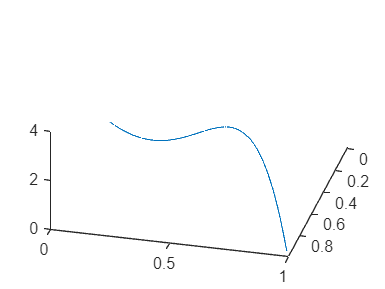

plot3(x, y, u_exact)

Generate base function

base_x = baseConstruct(n_el, x);
base_y = baseConstruct(n_el, y);

Define a function solve that solves the 2D FEA

function d = solve(x, y, n, f)
    B = zeros(2, 4);
    for i = 1:4      
        B(i,1) = base_x(i, x==0.2);
        B(i,2) = base_y(i, y==0,2);
    end
    d = B
end